# CPM monthly analysis

clc
clearvars
close all


## 환경설정


% 1. 입출력 파일 경로 
pathnm_csv='.\data input\csv_CPM\';
pathnm_pics='.\data input\pics_CPM\';

[checkF] = fnExistFolder( pathnm_csv );
[checkF] = fnExistFolder( pathnm_pics );

% 2. 기상 데이터 경로
weather_path = '.\data input\weather and holidays\';

% 3. 기상대 위치 설정
loc =108;

% 4. 에너지 데이터 경로
% path_data = ['.\data input\Y_monthly.csv'];
path_data = ['.\data input\Y_daily.csv'];

% 5. 건물명 (분석명) 설정
bld_str = 'test'; 





## Y 에너지 데이터 읽기


Y = readtable(path_data,'Format', '%s%s%f');

% Duration 
if numel(Y.USE_DATE{1}) == 6
    [y, ~, ~] = ymd(datetime(Y.USE_DATE,"InputFormat",'yyyyMM'));
elseif numel(Y.USE_DATE{1}) == 8
    [y, ~, ~] = ymd(datetime(Y.USE_DATE,"InputFormat",'yyyyMMdd'));
else 
    msg = 'ERROR : Check size of "Y.USE_DATE" '
    assert(false, msg)
end



date_start = min ( unique(y) );
date_end   = max ( unique(y) );
% date_end   = 2019;
yrs_vec    = date_start : date_end;


## X 기상데이터 읽기

% 경로 : Do not modify

% Region : Do not modify
fnm = [weather_path,'최적기상대목록 210217.xlsx'];
T_station = readtable(fnm);
T_wea = [];


for m = 1:numel(yrs_vec)
    
    if numel(Y.USE_DATE{1}) == 6
        fnm  = [weather_path,'T_weather_all_monthly_',num2str(yrs_vec(m)),'.csv'];
    elseif numel(Y.USE_DATE{1}) == 8
        fnm  = [weather_path,'T_weather_all_daily_',num2str(yrs_vec(m)),'.csv'];
    end

    opts = detectImportOptions(fnm);
    opts.SelectedVariableNames = {'loc','t_avg','USE_YM'};
    opts = setvartype(opts,{'t_avg'},'double');
    opts = setvartype(opts,{'USE_YM'},'char');
    T_wea0 = readtable(fnm,opts);
    T_wea = [T_wea ; T_wea0];
end
T_wea.Properties.VariableNames{'USE_YM'} = 'USE_DATE';
X = T_wea(T_wea.loc == loc,["USE_DATE","t_avg"]);


## Dataset

dataset = innerjoin(Y,X);
Tout    = (dataset.t_avg)';
Y_ini   = (dataset.EUSE)';


## 그룹화 변수 

 [date_index] = fn_CPM_date_index(Y);



## Fill missing

if numel(Y.USE_DATE{1}) == 6
    Y_ini(isnan(Y_ini)) = 0;
elseif numel(Y.USE_DATE{1}) == 8
    [Y_ini,TF] = fillmissing(Y_ini,'spline');
    Y_ini(isnan(Y_ini)) = 0;
else
end 


## CPM run


[save_T_stat, C_cookd, C_ZRE] = fn_CPM_run(Tout, Y_ini, pathnm_csv, pathnm_pics, bld_str, date_start, date_end);
save_T_stat.Es = repmat({'총계'},size(save_T_stat,1),1);
CPM_type_best = save_T_stat.CPM_TY;


## save CPM results


root_path = '.\data input\';
csv_name = ['CPM_Result_pk',bld_str];
writetable(save_T_stat, [pathnm_csv,csv_name, num2str(date_start), num2str(date_end)],"Delimiter","\t",'Encoding','UTF-8')


## CPM plot

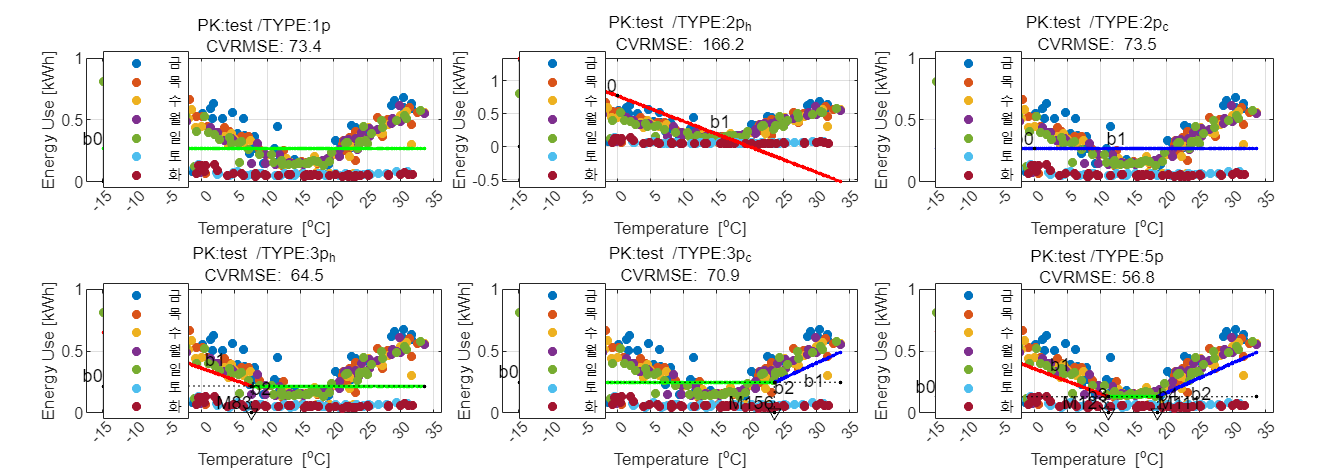

figure('units','normalized','outerPosition',[0.1 0.1 0.8 0.7])
t=tiledlayout(2,3, 'TileSpacing','compact', 'Padding', 'compact');

for k=1:6
    nexttile
    fn_CPM_plot_bestfit(1 , save_T_stat(k,:), C_cookd(k,:), C_ZRE(k,:), Tout, Y_ini, pathnm_csv, pathnm_pics, bld_str, date_start, date_end, CPM_type_best(k,:), date_index);
end

pic_name = ['CPM_bestfit0_Tot_pk',bld_str];
saveas(gcf, [pathnm_pics, pic_name, num2str(date_start), num2str(date_end)], 'png')